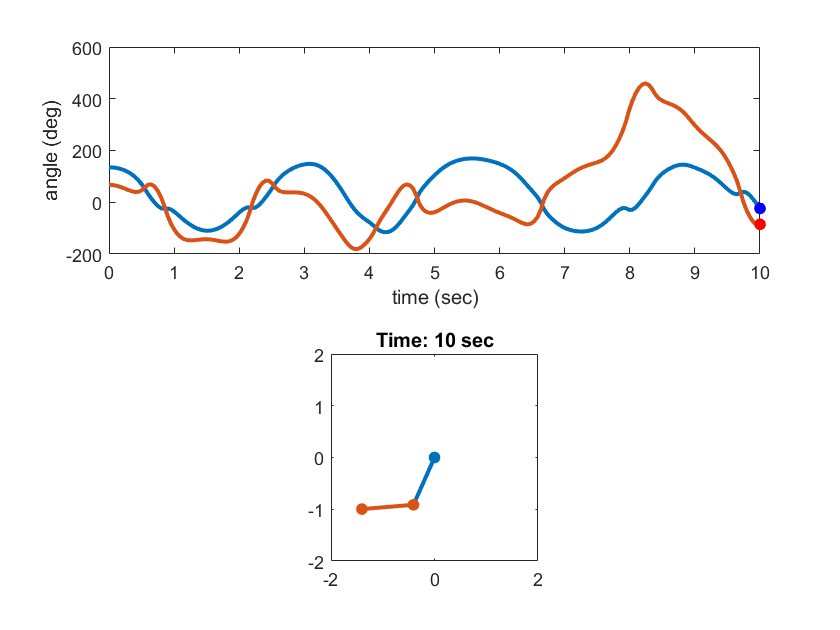

% Parameters and initial conditions
%   mass, link length, initial angles, simulation time
m = 1;
L = 1;
theta1 = 3*pi/4;
theta2 = 3*pi/8;
t = linspace(0, 10, 200);
% Solving ODE of a double pendulum
[T,Y] = ode45(@(t, x) double_pendulum(t, x, m, L), ...
    t, [theta1, theta2, 0, 0]);
% Calculating joint coordinates for animation purposes
x = [L*sin(Y(:,1)),  L*sin(Y(:,1))+L*sin(Y(:,2))];
y = [-L*cos(Y(:,1)), -L*cos(Y(:,1))-L*cos(Y(:,2))];
% Convert radians to degrees
ang = Y(:,1:2)*180/pi;
tiledlayout(2,1)            % Introduced in R2019b
nexttile                    % Introduced in R2019b
plot(T,ang,LineWidth=2)     % Name=value syntax introduced in R2021a!!
hold on
hh1(1) = plot(T(1),ang(1,1),Marker=".",MarkerSize=20,Color="b");
hh1(2) = plot(T(1),ang(1,2),Marker=".",MarkerSize=20,Color="r");
xlabel("time (sec)")
ylabel("angle (deg)")
hold off
nexttile
hh2 = plot([0,x(1,1);x(1,1),x(1,2)],[0,y(1,1);y(1,1),y(1,2)], ...
    Marker=".",MarkerSize=20,LineWidth=2);
axis equal
axis([-2*L 2*L -2*L 2*L])
ht = title("Time: "+T(1)+" sec");   % String arrays introduced in R2016b
for id = 1:length(T)
    set(hh1(1),XData=T(id),YData=ang(id,1))
    set(hh1(2),XData=T(id),YData=ang(id,2))
    set(hh2(1),XData=[0,x(id,1)],YData=[0,y(id,1)])
    set(hh2(2),XData=x(id,:),YData=y(id,:))
    set(ht,String="Time: "+T(id)+" sec")
    
    drawnow
    
end